# Using an ODE general solution structure

Instructions are in the task pane to the left. Complete and submit each task one at a time. 

Do not edit. This code defines the time interval and initial condition.

tRange = [0 5];
C0 = 0;

## Task 1

In this activity, you will solve the ODE

*d**C/d**t*=2*t*−1/2 *t^*2

from 0 to 5 with *C*(0)=0, where *C* is the concentration of a chemical in a reactor.

sol = ode45(@reactor, tRange, C0)

sol = struct with fields:
     solver: 'ode45'
    extdata: [1×1 struct]
          x: [0 0.5000 1 1.5000 2 2.5000 3 3.5000 4 4.5000 5]
          y: [0 0.2292 0.8333 1.6875 2.6667 3.6458 4.5000 5.1042 5.3333 5.0625 4.1667]
      stats: [1×1 struct]
      idata: [1×1 struct]


## Task 2

You can use the `deval` function to evaluate the solution at any point in the interval `tRange` by passing the solution structure and the point to `deval`.

`tRange` `=` `[``0` `4``]``;`

`sol` `=` `ode45``(``@``odefun``,``tRange``,``y0``)``;`

`y2` `=` `deval``(``sol``,``2``)``;`

C16 = deval(sol, 1.6);

## Task 3

Like many MATLAB functions, `deval` can also accept a vector of values for evaluation, as long as all values are in the original interval. This can be useful when you would like to visualize the solution.

`tspan` `=` `[``0` `4``]``;`

`sol` `=` `ode45``(``@``odefun``,``tspan``,``y0``)``;`

`t` `=` `linspace``(``1``,``3``,``20``)``;`

`y` `=` `deval``(``sol``,``t``)``;`

`plot``(``t``,``y``)`

Here, the vector `t` contains 20 equally spaced values from 1 to 3, and `y` contains the solution evaluated at those values.

t = linspace(0, 5, 100);
C = deval(sol, t);

## Task 4

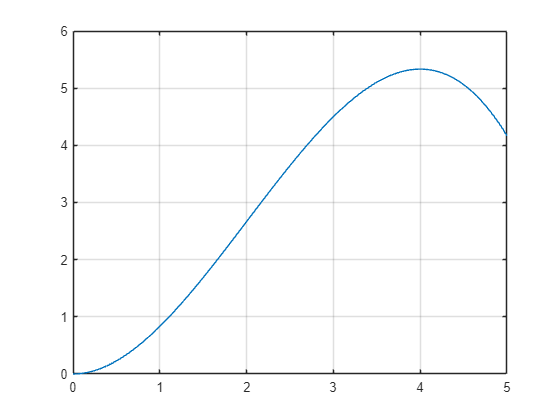

plot(t, C)
grid on

## Define the ODE function

function dCdt = reactor(t,C)
    dCdt = 2*t - 1/2*t^2;
end